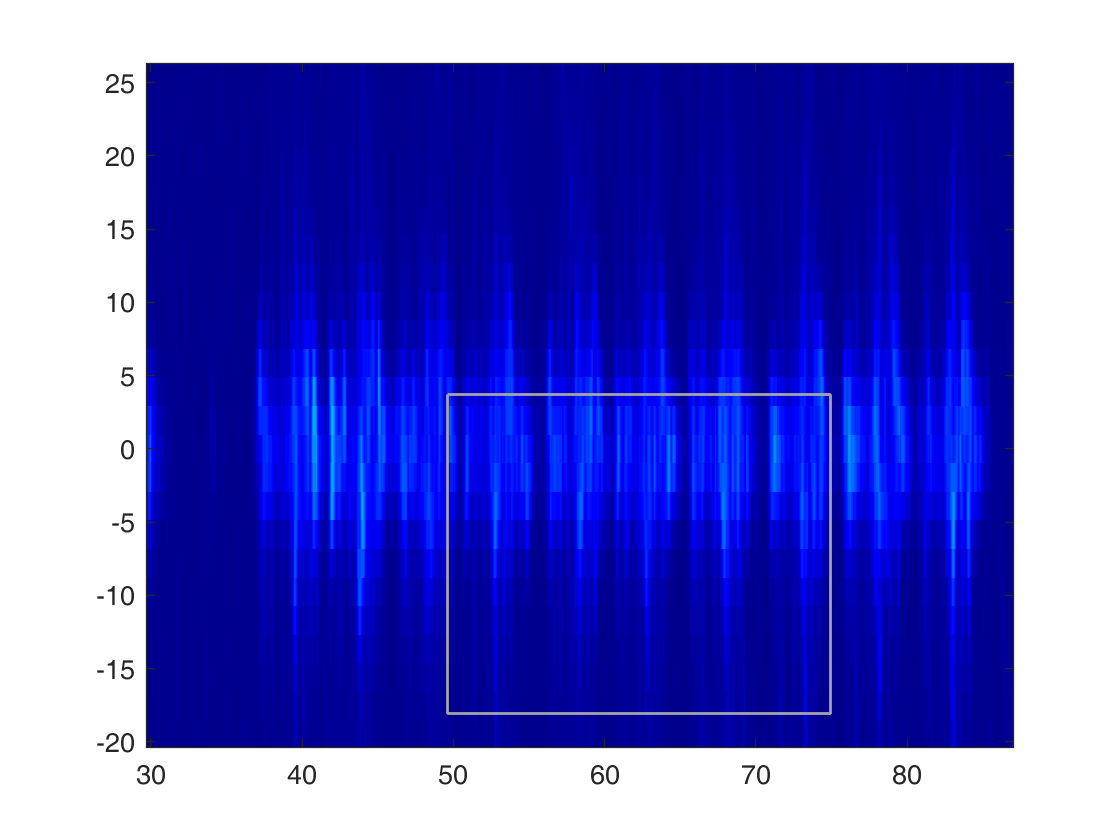

clear
[expConfig,csiMatrix,csiMatrixInfo] = readDatFile('U1_G4_N10_L_L1_D0_20200408_1.dat');

csi = getElemFromCsiMatrix(csiMatrix,csiMatrixInfo,...
    'MAC_Des', '00:16:EA:12:34:56', ...
    'MAC_Src', '00:16:EA:12:34:56', ...
    'Payloads','654321', ...
    'signal','csi');

processData = preprocess(csi, ...
    'suite', 'widance', ...
    'fc', [1,200], ...
    'fs', 1000, ...
    'pca', [10000,2:10], ...
    'stft', [512,16,5]);
hndl = imagesc(processData.time,processData.frequency,processData.psd);
hndl.Parent.YDir = 'normal'; colormap Jet;
ylim([-80 80]);

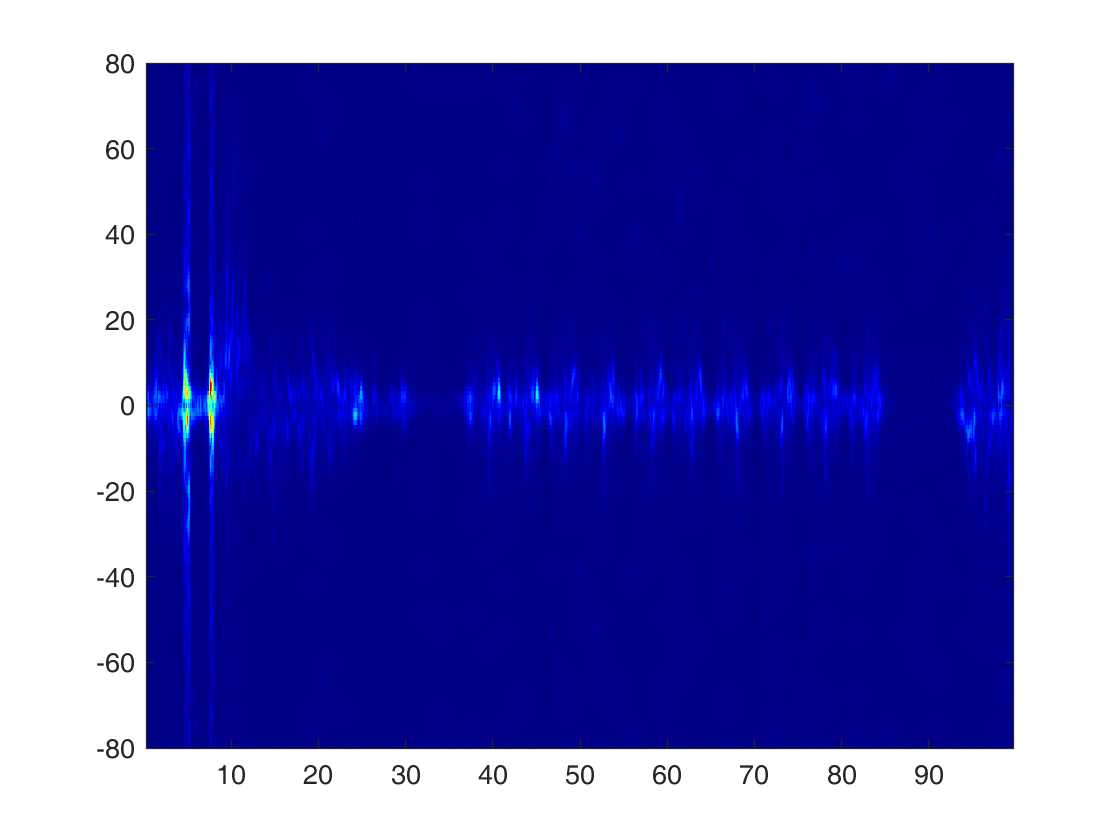

[data,frequency,time] = Preprocessing_WiDance(csi(:,3:end)',1000,[1 200],512,496,2:10,true);
% [data,~,frequency,time] = Preprocessing_CARM(csi(:,3:end)',2:10,1000,512,496);
hndl = imagesc(time,frequency,data);
hndl.Parent.YDir = 'normal'; colormap Jet;
ylim([-80 80]);